Corelyon Kan 

Computer Project 2 

Problem 1

1.1: Karman–Trefftz Transform 

- r(Note to team: Reference Ch. 17.1 Geometry of Analytic Functions: Conformal Mapping - Example 3 Joukowski Airfoil)

- Establish Variables

clear;
clf;
n = 1.95;%-------------------------------------------------Controls the Trailing edge angle
N = 180;%--------------------------------------------------Number of points around the circle 
b = .9;%---------------------------------------------------Denotes the scaling parameter (The chord length of the airfoil in the Z-plane)
e = exp(1);%-----------------------------------------------Assigns the mathematical value of e to variable to e
R = 1;%----------------------------------------------------R is the Radius of the Circle in the Zeta-Plane 
Epsilon = .1;%---------------------------------------------Epsilon is the real part of Zeta and denotes the x position of the circles center 
Sigma = .09;%----------------------------------------------Sigma is the imaginary part of Zeta and denotes the y position of the circles center 
Theta = linspace(0, 2 * pi, N);%---------------------------Generates even sequence of numbers specified by N from 0 to 2pi

- Plotting the circle in the zeta-plane 

Beta = Epsilon + 1i * Sigma;%------------------------------Denotes the circles center coordinate positon (Epsilon, Sigma) <---> (x,iy)
Zeta = Beta + R * (cos(Theta) + 1i * sin(Theta));%---------Equation of the circle in the zeta-plane (Cartesian) 

- Karman-Trefftz Transform: Mapping the Circle into the Airfoil in the z-plane

z = n * b * ((Zeta + b).^n + (Zeta - b).^n)./((Zeta + b).^n - (Zeta - b).^n);%---Karman-Trefftz Transformation
disp(abs(Beta-1))

    0.9045



- Plotting the circle in the zeta-plane and plotting the airfoil in the z-plane

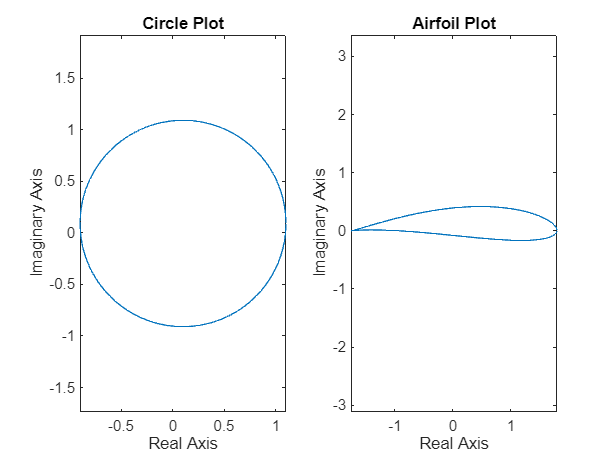

figure;
subplot(1,2,1);
plot(real(Zeta), imag(Zeta))
title("Circle Plot")
xlabel("Real Axis")
ylabel("Imaginary Axis")
axis equal

subplot(1,2,2)
plot(real(z), imag(z))
title("Airfoil Plot")
xlabel("Real Axis")
ylabel("Imaginary Axis")
axis equal